# The SIR Model

#### **The Model**

The SIR model is a compartmental model in epidemiology. A compartmental model divides the whole poulation in different groups and describes with a set of equations how the groups interact. In the SIR-model the three compartments are: the susceptible (S), the infected (I) and the removed (R). The flow of individuals from one compartment to another is described in terms of three differential equations, reported below, while the total number of the population stays the same in time: $N=S_0+I_0+R_0=S(t)+I(t)+R(t)$.

At initial conditions $S_0$, $I_0$ and $R_0$, the compartment S contains most of the population, whereas as little as 1 individual might account as infected and none belongs in the compartment R. As the disease spreads, individuals are relocated either from S to I when they contract the disease, or from I to R if they recover. It is assumed that immunity persists once it has been developed, that is, there is no flow from R to S.

The image below shows what the block diagram for the SIR model looks like.

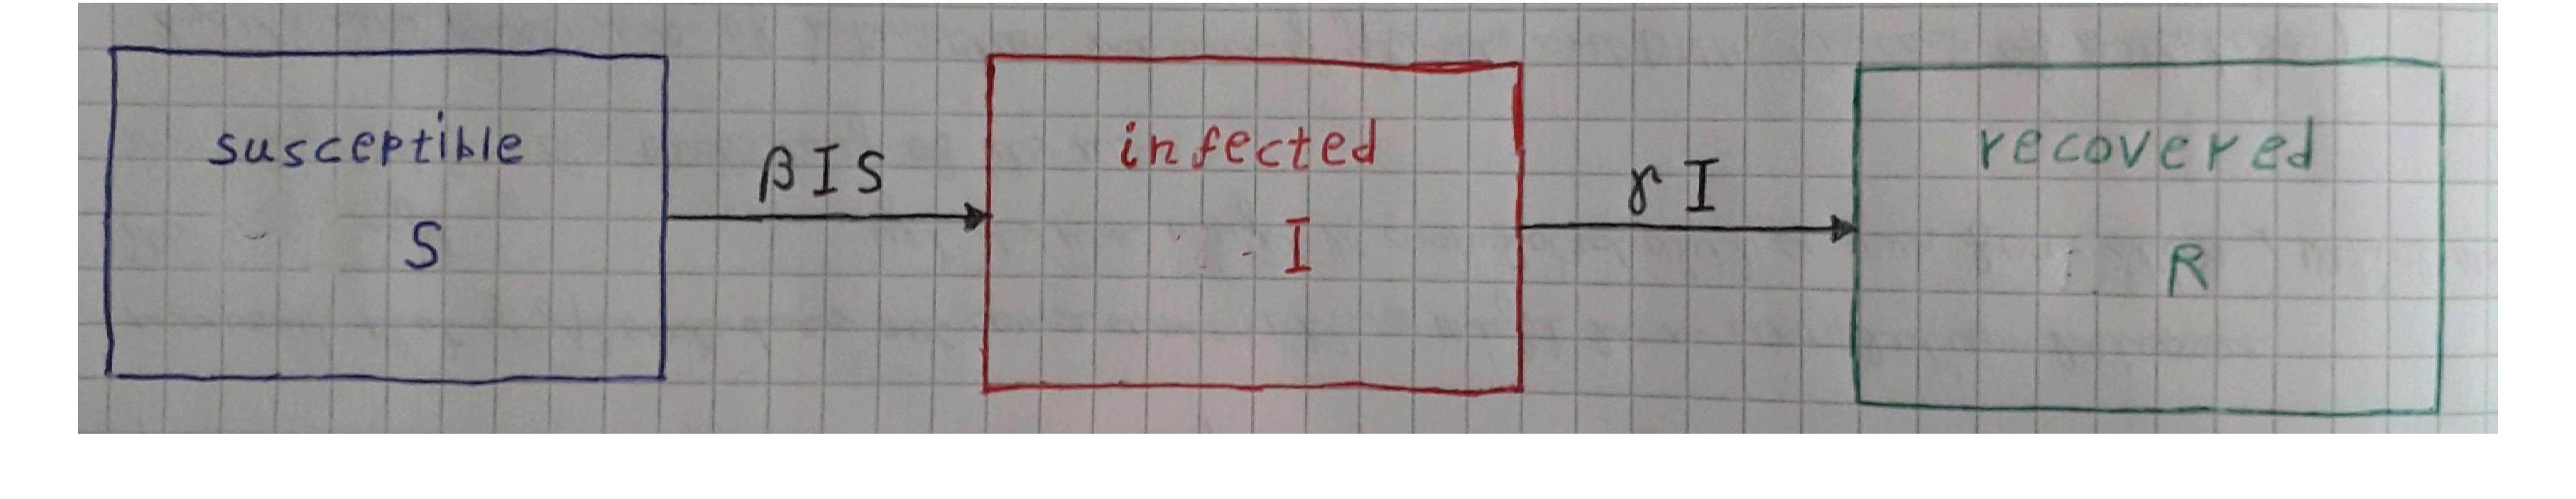

imshow('SIR_block_diagram.jpg')

The differential equations of the SIR model are:


$$\frac{dS}{dt}=-\beta I S,\\
\frac{dI}{dt}=\beta IS-\gamma I,\\
\frac{dR}{dt}=\gamma I.
$$


The parameters $\beta$ and $\gamma$are:

- $\beta$ is referred to as the infection rate and is defined as the product between the infection probability $p$ and the contact rate $c$, divided by the total population. In fact, its value depends on the transmissability of the disease, which is accounted for with $p$, and the frequency that members of a population gather for social reasons, which is expressed as $c$.

- $\gamma$ corresponds to the recovery rate. Its value relies on the virulence or pathogenicity of the organism responsible for the disease as well as the average physical and mental conditions of the population, which can also affect how drammatically an individual will experience related symptoms.

**Mathematical Properties of the Model**

- An important parameter in modelling of epidemics is the **basic reproduction number**, which is expressed as $R_0$ and tells how many individuals get infected by one person with the disease. In other words, $R_0$ shows the level of contagiousness or infectiveness of a population unit in the S compartment. Here below we derive the expression of $R_0$:

            
$$\frac{dI}{dt}(t=0) = \beta I_0 S_0 - \gamma I_0$$


            Let's stay positive and assume that the expression above is less than 1, so less than one person gets infected every time step $dt$.

            
$$\Longleftrightarrow \beta I_0 S_0 - \gamma I_0 < 0 \Longleftrightarrow \beta I_0 S_0 < \gamma I_0 \Longleftrightarrow \frac{\beta S_0}{\gamma}<1$$


            As we can see, our assumption depends on the infection and recovery rates $\beta$ and $\gamma$. More precisely, their ratio, also known as $R_0$, determines the infection dynamics.

            
$$\Longrightarrow R_0= \frac{\beta}{\gamma}$$


            for $S_0 \approx \textit{entire population}$

- The basic reproduction number can be employed as a threshold for the establishment of **herd immunity** within the community of interest. If $R_0 < 1$, one infected person can spread the disease to less than one population unit, thus herd immunity is achieved over time, whereas if $R_0>1$, one infected person will spread the disease to more than one population unit and herd immunity is hindered.

            $R_0<1$: establishment of herd immunity

            $R_0>1$: outbreak of the disease

            Importantly, $R_0$ does not stay constant across outbreaks of the same disease, as it depends on several environmental as well as social factors that vary across communities, regions and history.

- Like the basic reproduction number, the peak of an outbreak is an element which can also arise a huge interest and affect policies as well as behavioural and psychological conditions of the population. The maximum value of infected individuals is represented with $I_{max}$, along with the point in time when this peak occurs:                                                                                                                                                                                                                                                                                                                                                                  

            
$$I_{max}=\frac{N}{R_0}(R_0-1-\ln{R_0})$$


## Solution with Euler method

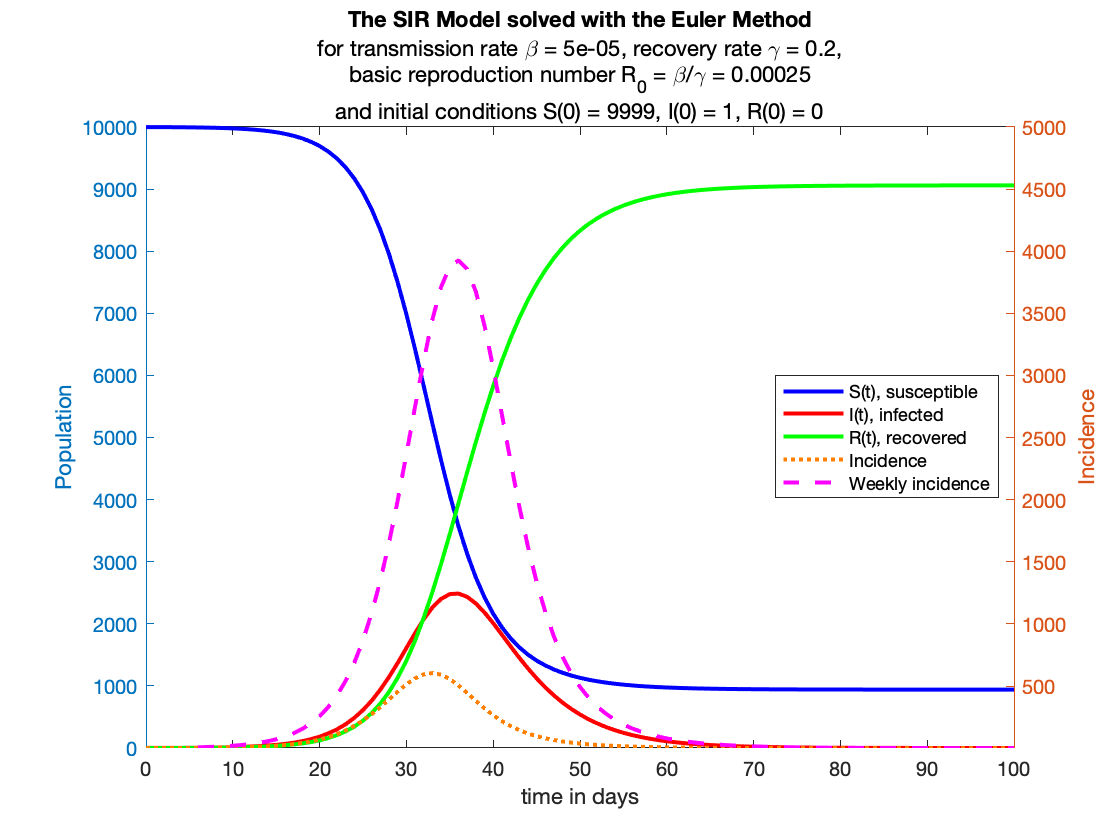

figure;

%%% The initial values

tmax = 100;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);
R = zeros(1, tmax + 1);

S(1) = 9999;
I(1) = 1;
R(1) = 0;
N=S(1)+I(1)+R(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.1;  % infection probability 
c=5;    % contact rate

beta = p*c/N;
gamma = 0.2;

R_0=beta/gamma;


%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
        
    S(t+1) = S(t) - beta*I(t)*S(t) ;   
    I(t+1) = I(t) + (beta*I(t)*S(t)) - gamma*I(t);    
    R(t+1) = R(t) + gamma*I(t);
    
    Incidence(t+1) = beta*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end


%%%% The plot

yyaxis left
plot(T, S, 'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(T, I, 'r','LineWidth',2,'LineStyle',"-");
plot(T, R, 'g','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right 
plot(T, Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(T(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylim([1 5000]);
ylabel('Incidence');

title('The SIR Model solved with the Euler Method')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1)),', R(0) = ',num2str(R(1))]})
legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered','Incidence', 'Weekly incidence', 'Location', 'east')

xlabel('time in days');
xlim([0 100]);

hold off;

## Solution with ode45

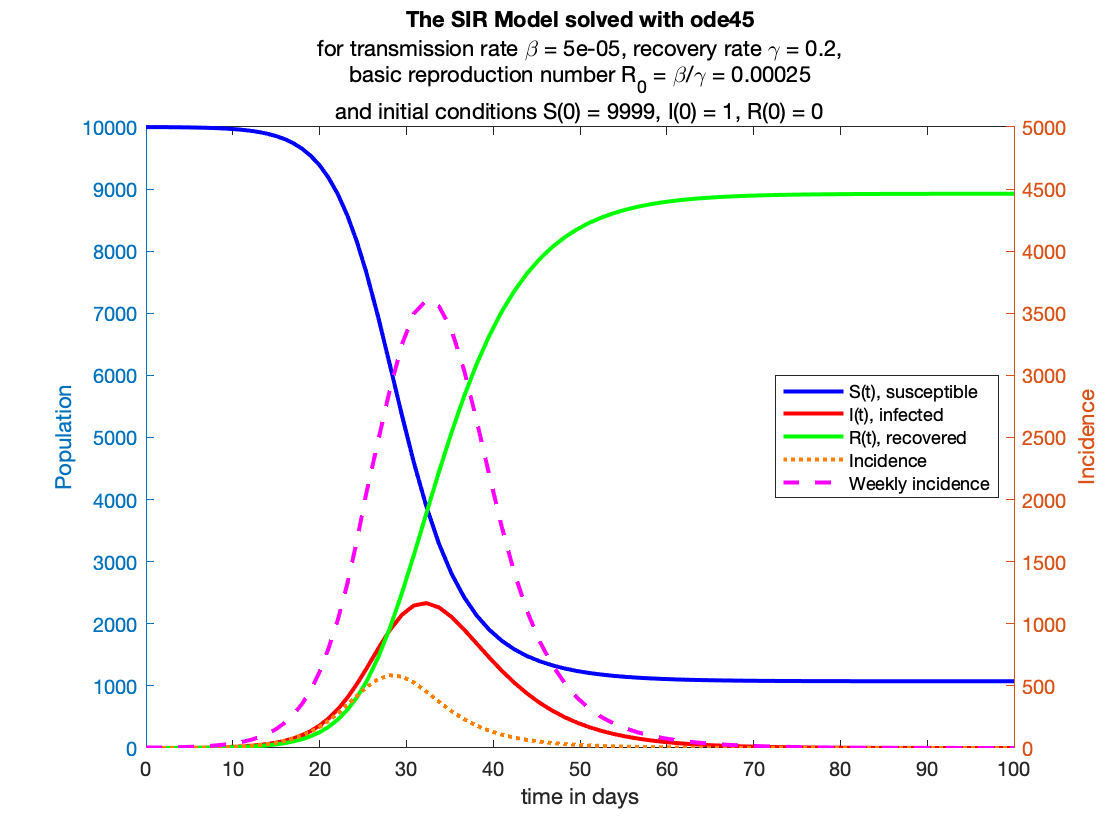

figure;

%%%% The parameters and the initial values

tRange = [0 100];
gamma = 0.2;
beta = 0.00005;
R_0=beta/gamma;
Y0 = [9999; 1; 0];

[tSol,YSol] = ode45(@SIRmodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);

Incidence = beta*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end

yyaxis left
plot(tSol,S,'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(tSol,I,'r','LineWidth',2,'LineStyle',"-");
plot(tSol,R,'g','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right
plot(tSol,Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(tSol(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylabel('Incidence');
ylim([0 5000]);

legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered','Incidence', 'Weekly incidence', 'Location', 'east');
title('The SIR Model solved with ode45');
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3))]})

xlabel('time in days');
xlim([0 100]);

hold off;

function dYdt = SIRmodel(t,Y)  % TODO - Write the function declaration. Name the function SIRmodel

    % Extract S, I, and R from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    R = Y(3); % recovered
    
    % Define the constants beta and gamma
    beta = 0.00005;
    gamma = 0.2;
    
    % Define dSdt, dIdt, dRdt from the ODEs
    dSdt = -beta*S*I;
    dIdt = beta*S*I - gamma*I;
    dRdt = gamma*I;
    
    % Create output column vector dYdt
    dYdt = [dSdt; dIdt; dRdt];
    
end